figure; plot(experiment.sound_events.fullSoundCleaned(experiment.conditionVector.aluminum))

aud_aluminum = aud_denoise(experiment.conditionVector.aluminum)

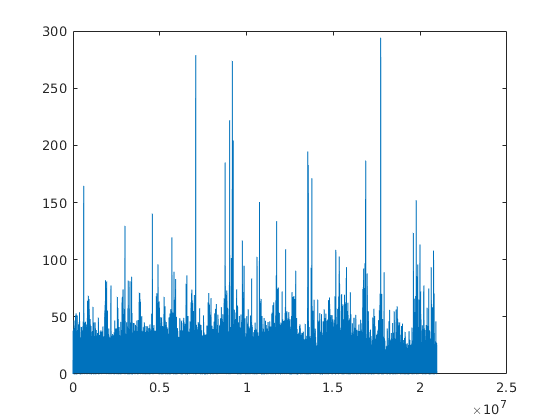

thr = 30

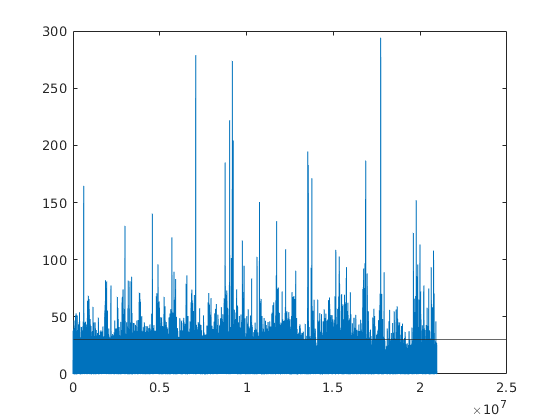

thr = 30

j = event_detection(aud_aluminum,150);

times = experiment.conditionVector.aluminum(j)

times = 1×6830 int64 row vector
   7815539   7819075   7823554   7833146   7837704   7843852   7847813   7850954   7857132   7859622   7866262   7867014   7872218   7872824   7888066   7889496   7892449   7896436   7896892   7898286   7899924   7903592   7904378   7907212   7913000   7914398   7916800   7918066   7934126   7938107   7941270   7950786   7958692   7959123   7963640   7968076   7973449   7978132   7985144   7995228   7997284   7998429   7999738   8002356   8002818   8003592   8012850   8014237   8014400   8019100


[hh] = createRaster(double(times),unit282,2)

unit282_psth = psth(hh,10);

jj = createRaster(double(times),unit365,2)

[unit365_psth,time_vec] = psth(jj,10)

event_matrix = experiment.sound_events.fullSoundCleaned(event_matrix)

mm = mean(event_matrix)

p = zeros(200,38)'

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

for i = 1:9
    h = createRaster(double(times),nonzeros(experiment.Units.good.times(i,:)),2);
    p(i,:) = psth(h,10);
end

for k = 1:29
    h = createRaster(double(times),nonzeros(experiment.Units.mua.times(k,:)),2);
    p(i+k,:) = psth(h,10);
end

for moti=1:5874
[~,times_whisk(moti)] = min(abs(experiment.Cams.whsiking.csv_aligned_frames - double(times(moti))));
end

whisk_mat = ones(5874,800);

whisk_mat = whisk_mat+[-400:399];

whisk_mat = whisk_mat + times_whisk';

whisk_all = mot_filt(whisk_mat);

%%% get population graphs


statAll.right = [];
statAll.left = [];
allUnitsAll = [];


%load experiment and stat file

allUnits = [experiment.Units.perCondition.good.alum.FR;experiment.Units.perCondition.mua.alum.FR];
allUnits(:,2) = [experiment.Units.perCondition.good.muted.FR;experiment.Units.perCondition.mua.muted.FR];
allUnits(:,3) = [experiment.Units.perCondition.good.non.FR;experiment.Units.perCondition.mua.non.FR];

statAll.right = [statAll.right;stat.Right]
statAll.left = [statAll.left;stat.Left]

allUnitsAll = [allUnitsAll;allUnits]

clear experiment stat allUnits